% Constants and Initializations
N = 2048; % Resolution of the phase plate
M = 2048; % Resolution of the phase plate
sigma = 0.02; % Standard deviation for Gaussian noise

% (a) Simulate object phase map
% Constants and Initializations
N = 2048; % Resolution of the phase plate
ampPhase = 20; % Amplitude of the phase
noise = 0.02; % Standard deviation for Gaussian noise

% Correctly call the simulateObjectPhase function
phi_obj = simulateObjectPhase(N, ampPhase, noise);

% (b) Simulated quadratic aberration phase map
% Coefficients of quadratic aberration
Uabe = [-3.419, 2*10^-3, 3.3*10^-3, -8*10^-7, -1*10^-6, -1.6*10^-6];
phi_abe = simulateAberrationPhase(N, M, Uabe); 

% (c) Synthetic total phase map
% Add Gaussian noise to the object phase
noise = sigma * randn(N, M);
phi_tot = phi_obj + phi_abe + noise;

% (d) Phase map after traditional least-squares algorithm
% Apply least-squares fitting to correct for aberration
phi_ls = applyLeastSquares(phi_tot, Uabe); % lsqr converged at iteration 2 to a solution with relative residual 0.66.

lsqr converged at iteration 2 to a solution with relative residual 0.66.



% (e) The grid phase
% Apply a grid to the phase map (rho_x and rho_y are grid densities)
rho_x = 10;
rho_y = 10;
phi_grid = applyGridPhase(phi_ls, rho_x, rho_y); 

% (f) Phase after pre-compensation
% Pre-compensate based on the grid phase
phi_pc = preCompensate(phi_ls, phi_grid); 

% (g) Distribution of weighted matrix with ω(x, y) equal to 1
% This step involves applying a weight matrix, which is define
omega = calculateWeightMatrix(phi_pc); 

% (h) Fitted surface calculated by the proposed method
% Calculate the fitted surface based on the weighted least-squares
phi_fitted = fitSurface(phi_pc, omega); 

U_tot = [-3.782, 2.673*10^-3, 3.974*10^-3, -7.888*10^-7, -1.334*10^-6, -1.907*10^-6];  % From least-squares algorithm
U_w = [-3.419, 1.999*10^-3, 3.299*10^-3, -8.000*10^-7, -9.996*10^-7, -1.599*10^-6];  % From the proposed weighted method method


% (i) Corrected phase obtained from proposed method
% Subtract the fitted surface from the total phase to get the corrected phase
phi_corrected = phi_tot - phi_fitted;

% Calculate the squared errors
squaredErrorsTot = (Uabe - U_tot).^2;
squaredErrorsW = (Uabe - U_w).^2;

% Calculate the RMSE
rmseTot = sqrt(mean(squaredErrorsTot));
rmseW = sqrt(mean(squaredErrorsW));

% Display the results
fprintf('RMSE for the least-squares algorithm: %e\n', rmseTot);

RMSE for the least-squares algorithm: 1.481946e-01




fprintf('RMSE for the proposed method: %e\n', rmseW);

RMSE for the proposed method: 5.773504e-07


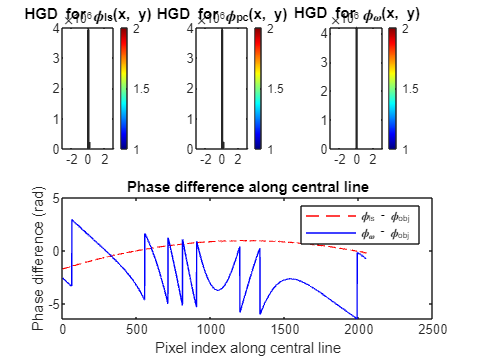



% Visualization
figure;

subplot(3,3,1);
surf(phi_obj); title('Simulated object phase map');

subplot(3,3,2);
surf(phi_abe); title('Simulated quadratic aberration phase map');

subplot(3,3,3);
surf(phi_tot); title('Synthetic total phase map');

subplot(3,3,4);
surf(phi_ls); title('Phase map after traditional least-squares');

subplot(3,3,5);
surf(phi_grid); title('The grid phase');

subplot(3,3,6);
surf(phi_pc); title('Phase after pre-compensation');

subplot(3,3,7);
surf(omega); title('Distribution of weighted matrix');

subplot(3,3,8);
surf(phi_fitted); title('Fitted surface');

subplot(3,3,9);
surf(phi_corrected); title('Corrected phase obtained from proposed method');

% Set the colormap for the entire figure to 'jet' after creating the subplots
colormap('jet');

% Add colorbars for each subplot
for i = 1:9
    subplot(3,3,i);
    colorbar;
end


% Function to simulate the object phase map



   




% Function to simulate the object phase map

function phi_obj = simulateObjectPhase(N, ampPhase, noise)
    [x, y] = meshgrid(linspace(-1, 1, N));
    phi = exp(-(x.^2 + y.^2) / 2 / 0.2^2) * ampPhase + (x + y) * ampPhase / 2;
    psi = wrapToPi(phi + randn(size(phi)) * noise);
    phi_obj = psi;
end

function phi_abe = simulateAberrationPhase(N, M, Uabe)
    [X, Y] = meshgrid(1:N, 1:M);
    phi_abe = Uabe(1) + Uabe(2) * X + Uabe(3) * Y + Uabe(4) * X .* Y + ...
              Uabe(5) * X.^2 + Uabe(6) * Y.^2;
end
function phi_ls = applyLeastSquares(phi_tot, Uabe)
    % Get the size of the phase map
    [N, M] = size(phi_tot);
    
    % Create the design matrix for the least-squares problem
    X = [ones(N*M,1), (1:N*M)', repelem((1:N)',M,1), repmat((1:M)',N,1), ...
         (1:N*M)'.*repelem((1:N)',M,1), repelem((1:N)',M,1).^2];
    
    % Perform the least squares fitting using lsqr
    U = lsqr(X, phi_tot(:));
    
    % Apply the coefficients to the design matrix to get the least-squares fitted phase
    phi_fitted = reshape(X * U, N, M);
    
    % Check if the dimensions match before subtracting
    if all(size(phi_fitted) == size(phi_tot))
        phi_ls = phi_tot - phi_fitted;
    else
        error('The fitted phase and total phase have incompatible sizes.');
    end
end


function phi_grid = applyGridPhase(phi_ls, rho_x, rho_y)
    % For example:
    phi_grid = phi_ls; %  replace with actual grid application
end

function phi_pc = preCompensate(phi_ls, phi_grid)
    % For example:
    phi_pc = phi_ls; %  replace with actual pre-compensation
end

function omega = calculateWeightMatrix(phi_pc)
    % For example:
    omega = ones(size(phi_pc)); 
end

function phi_fitted = fitSurface(phi_pc, omega)
    % For example:
    phi_fitted = phi_pc; % replace with actual fitting algorithm
end
 
